% Normalisierung der Messdaten: Inputs: range einzeln
% Outputs: range aller T_in => zur leichteren Interpretation und
% Umrechenbarkeit Tmin = ; Tmax =

D = readtable("cleanedData.txt");

%D = readtable(eingeteilteDaten)


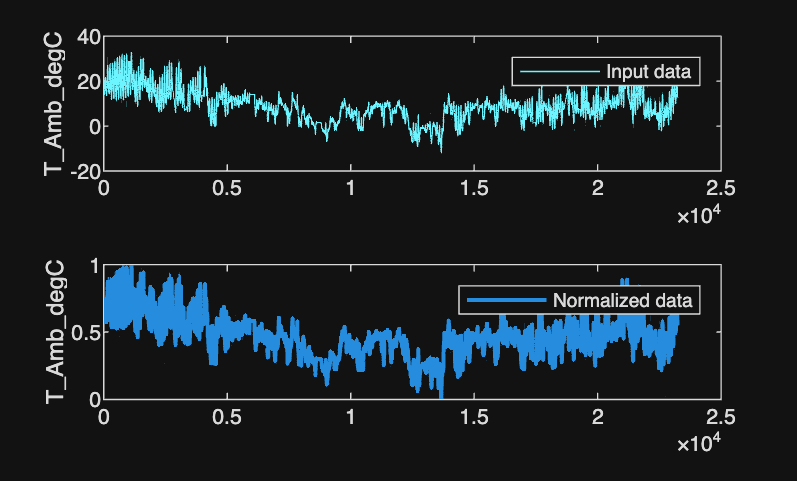

% Normalize Data
[normalizedData,centerValue,scaleValue] = normalize(D,"range", ...
    "DataVariables",["T_Amb_degC","Q_heat","Q_sol","Q_int","EG_LivingKitchen_degC", ...
    "EG_HallwayEntrance_degC","EG_Utilities_degC","EG_Dressing_degC", ...
    "EG_Sleeping_degC","EG_Bath_degC","EG_GuestBath_degC","EG_Server_degC", ...
    "OG_Office_degC","OG_Sleeping_degC","OG_Bath_degC"],"ReplaceValues",false);

% Display results
figure
tiledlayout(2,1);
nexttile
plot(D.T_Amb_degC,"SeriesIndex",6,"DisplayName","Input data")
legend
ylabel("T_Amb_degC","Interpreter","none")

nexttile
plot(normalizedData.(17),"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Normalized data")
legend
ylabel("T_Amb_degC","Interpreter","none")

set(gcf,"NextPlot","New")
centerValue

centerValue = 1×15 table
    T_Amb_degC    Q_heat    Q_sol    Q_int    EG_LivingKitchen_degC    EG_HallwayEntrance_degC    EG_Utilities_degC    EG_Dressing_degC    EG_Sleeping_degC    EG_Bath_degC    EG_GuestBath_degC    EG_Server_degC    OG_Office_degC    OG_Sleeping_degC    OG_Bath_degC
    __________    ______    _____    _____    _____________________    _______________________    _________________    ________________    ________________    ____________    _________________    ______________    ______________    <s

scaleValue

scaleValue = 1×15 table
    T_Amb_degC    Q_heat    Q_sol    Q_int     EG_LivingKitchen_degC    EG_HallwayEntrance_degC    EG_Utilities_degC    EG_Dressing_degC    EG_Sleeping_degC    EG_Bath_degC    EG_GuestBath_degC    EG_Server_degC    OG_Office_degC    OG_Sleeping_degC    OG_Bath_degC
    __________    ______    _____    ______    _____________________    _______________________    _________________    ________________    ________________    ____________    _________________    ______________    ______________    <


%oder: hiermit nur Variablen 5-16 der Rest normal normalisieren
% To normalize multiple variables to the same range in MATLAB, you can use min-max normalization. This process scales the values of each variable to fit within a specified range, typically [0, 1] or [-1, 1]. Here's how you can do it for several variables, ensuring they all fit within the same range.

% Define the desired range
%rangeMin = 0;
%rangeMax = 1;

% Initialize the normalized data matrix
%normalizedData = zeros(size(D));

% Normalize each variable to the same range
%for i = 5:size(D, 2)
 %   minVal = min(D(:, i));
 %   maxVal = max(D(:, i));
 %   normalizedData(:, i) = (D(:, i) - minVal) / (maxVal - minVal) * (rangeMax - rangeMin) + rangeMin;
%end

% Display the original and normalized data
%disp('Original Data:');
%disp(D(1:5, :)); % Display the first 5 rows for brevity
%disp('Normalized Data:');
%disp(normalizedData(1:5, :)); % Display the first 5 rows for brevity


%writetable(normalizedData,"normalizedData")